# Synthesis of the connection of three pipes

close all;
clear all;
clc;

%including all parent folders up to the file 'code', this makes visible all
%files within this code
addingPathParentFolderByName('COMSOL_CNN_height_28um_Q_5_uL_tetrazine_Design_3');

Adding matlab path to: D:\code\NN_molecular_communications\Section_IV_BioComputing\COMSOL_CNN_height_28um_Q_5_uL_tetrazine_Design_3


#### Parameters

%call to the parameters file
Parameters

height_pipe=28 um


c_Tartrazine_ini = 0.0845

c_max = 0.0845

mu = 9.9792e-04

D_coeff = 4.9000e-10

Q_inlet_CNN=2 uL/min


#### Péclet condition

Pe_cond=zeros(length(w_vec),length(l_vec));

for i_w=1:length(w_vec)

    %i_r/length(r_vec)*100

    for i_l=1:length(l_vec)

        %Hydraulic Resistance
        % R=12*mu*l_vec(i_l)/(1-0.63*height_pipe/w_vec(i_w))*1/(height_pipe^3*w_vec(i_w));
        
        %Volumetric flow
        % Q=p0/R;
        

        %Mean velocity
        %Circular channel of radius r_vec(i_r) [2, pag. 54]
        % v_char=r_vec(i_r)^2*p0/(3*mu*l_vec(i_l))
        %Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
        v_char=Q/(w_vec(i_w)*height_pipe);

        %Peclet number, see [3, Eq. below 11] 
        Pe=v_char*height_pipe/D_coeff;

        %Evaluating the Effective Diffusion coefficient
        %Circular channel: [1, Eq.(4.54) pp.77]
        %D_eff=r_vec(i_w)^2*v_char^2/48/D_coeff;
        %Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
        %Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
        % D_eff=D_coeff*(1+1/200*Pe^2);

        % %Péclet number, circular channel this evaluation follows [1,Eq. (4.44) pp.75]
        % Pe=r_vec(i_r)*v_char/D_coeff;
        
        %Validating the diffusion within the pipe
        %Diffusion occurred along the radial axis and x-axis
        if(Pe<4*l_vec(i_l)/height_pipe && Pe>1)
            Pe_cond(i_w,i_l)=1;

        %Diffusion hasn't occurred along the radial axis and x-axis
        elseif(Pe>4*l_vec(i_l)/height_pipe)
            Pe_cond(i_w,i_l)=0;
            %recording the lenght of the pipe
            if(i_w==1)
                l_vec_max_idx=i_l;
            end
            if(i_w==length(w_vec))
                l_vec_min_idx=i_l;
            end
        
        %Diffusion hasn't occurred along the axis
        elseif (Pe<1)
            Pe_cond(i_w,i_l)=-1;
        end
    end
end


## Plotting the Pe_cond matrix

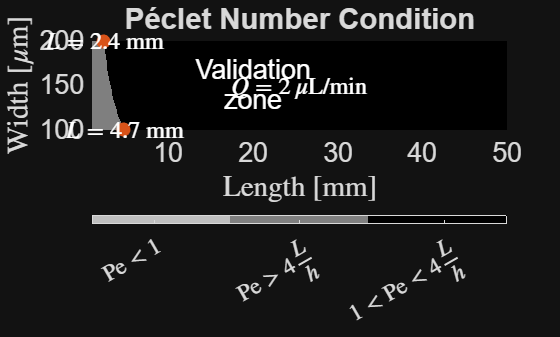

figure;

% Plot for all conditions in a single plot
hold on;
imagesc(l_vec*1e3, w_vec*1e6, Pe_cond); hold on
% colormap([0.8500 0.3250 0.0980; 0.9290 0.6940 0.1250; 0.0072 0.4470 0.7410]); % Colors for 0, -1, and 1
colormap([0.75, 0.75, 0.75; 0.5, 0.5, 0.5; 0, 0, 0]); % Colors for 0, -1, and 1
caxis([-1 1]); % Set color axis limits to match Pe_cond values

text(20,150,{'Validation', 'zone'},'FontSize',fontsize,'Color','w','HorizontalAlignment','center');

text(l_vec(end/2)*1e3,w_vec(end/2)*1e6,{strcat('$Q=',num2str(Q*6e10,2),'\, \mu$L/min')},'FontSize',fontsize-2,'Color','w','HorizontalAlignment','center',Interpreter='latex');

%lenght and width annotations
plot(l_vec(l_vec_max_idx)*1e3, w_vec(1)*1e6,'o','Color',"#D95319",MarkerFaceColor="#D95319",MarkerSize=10);
plot(l_vec(l_vec_min_idx)*1e3, w_vec(end)*1e6,'o','Color',"#D95319",MarkerFaceColor="#D95319",MarkerSize=10);
text(l_vec(l_vec_max_idx)*1e3,w_vec(1)*1e6,{strcat('$L=',num2str(l_vec(l_vec_max_idx)*1e3,2),' $ mm')},'FontSize',fontsize-2,'Color','w','HorizontalAlignment','center',Interpreter='latex');
text(l_vec(l_vec_min_idx)*1e3,w_vec(end)*1e6,{strcat('$L=',num2str(l_vec(l_vec_min_idx)*1e3,2),'$ mm')},'FontSize',fontsize-2,'Color','w','HorizontalAlignment','center',Interpreter='latex');

% Create a colorbar and set its ticks and labels
cb = colorbar('Ticks', [-0.7, 0, 0.7], 'TickLabels', {'$\mathrm{Pe}<1$', '$\mathrm{Pe}>4\frac{L}{h}$', '$1<\mathrm{Pe}<4\frac{L}{h}$'}, 'TickLabelInterpreter', 'latex', 'FontSize', fontsize-3,'Location','southoutside');
% cb.Layout.Tile='south';

% Set the color of the colorbar with transparency
%set(colorbarHandle, 'alpha', 0.5); % RGBA format, where A is the alpha value
%alpha(0.5);

xlabel('Length [mm]','Interpreter','latex');
ylabel('Width [$\mu$m]','Interpreter','latex');
axis([l_vec(1)*1e3 l_vec(end)*1e3 w_vec(1)*1e6 w_vec(end)*1e6])
set(gca, 'YDir', 'normal');
title('Péclet Number Condition');
set(gca,'FontSize',fontsize ,'YDir', 'normal'); % To display the y-axis in the correct direction
hold off;

### Peak time and peak amplitude vs width and length

Q_min=inf;
Q_max=-inf;

syms t

%length of the pipe
total_points=1e2;
w_vec=linspace(100e-6,200e-6,total_points);%selected based on the mixer dimenssion in [4, Fig. 3]
l_vec=linspace(17,50,total_points)*1e-3;%selected based on the Peclet number condition

%defining the time interval
total_points_time=1e2;
t_ini=1e-7;
t_end=10;
t_vector = linspace(t_ini,t_end,total_points_time);
time_sampling=t_vector(2)-t_vector(1);

h_amp=zeros(length(w_vec),length(l_vec));
h_tau=zeros(length(w_vec),length(l_vec));

Q=Q_inlet_CNN; 

for i_w=1:length(w_vec)

    i_w/length(w_vec)*100

    for i_l=1:length(l_vec)

        %Hydraulic Resistance
        % R=12*mu*l_vec(i_l)/(1-0.63*height_pipe/w_vec(i_w))*1/(height_pipe^3*w_vec(i_w));

        %Volumetric flow
        % Q=p0/R;

        %Mean velocity
        %Circular channel of radius r_vec(i_r) [2, pag. 54]
        % v_char=r_vec(i_r)^2*p0/(3*mu*l_vec(i_l))
        %Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
        v_char=Q/(w_vec(i_w)*height_pipe);

        %Peclet number, see [3, Eq. below 11] 
        Pe=v_char*height_pipe/D_coeff;

        %Evaluating the Effective Diffusion coefficient
        %Circular channel: [1, Eq.(4.54) pp.77]
        %D_eff=r_vec(i_w)^2*v_char^2/48/D_coeff;
        %Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
        %Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
        D_eff=D_coeff*(1+1/200*Pe^2);      

        %Validating the diffusion within the pipe
        %Diffusion occurred along the radial axis and x-axis
        if(Pe<4*l_vec(i_l)/height_pipe && Pe>1)
            h_tau(i_w,i_l)=l_vec(i_l)/v_char-2*D_eff/v_char;
            %Evaluating the concentration of the straigth channel
            c=1./2.*erfc((l_vec(i_l)-v_char*t)./(2*sqrt(D_eff*t)));
            %Evaluating the channel impulse response
            h=diff(c,t);
            h_amp(i_w,i_l)=subs(h,h_tau(i_w,i_l));
            %for validation purposes only
            % figure;
            % figure;plot(t_vector,subs(h,t_vector)); grid on;
            % h_vs_t=subs(h,t_vector);
            % [h_amp(i_w,i_l),idx]=max(h_vs_t);
            % h_tau(i_w,i_l)=t_vector(idx);
            %Fiding the peak of the channel ımpulse response

            % if(Q<Q_min)
            %     Q_min=Q;
            %     Q_min_w_idx=i_w;
            %     Q_min_l_idx=i_l;
            % end
            % 
            % if(Q>Q_max)
            %     Q_max=Q;
            %     Q_max_w_idx=i_w;
            %     Q_max_l_idx=i_l;
            % end

        %Diffusion hasn't occurred along the radial axis and x-axis
        elseif(Pe>4*l_vec(i_l)/height_pipe)
            disp(['Concentration is not constant along the x-axis, Pe=',num2str(double(Pe)),' is larger than ',num2str(4*l_vec(i_l)/height_pipe)])
            i_w
            i_l


        %Diffusion hasn't occurred along the axis
        elseif (Pe<1)
            disp(['Diffusion hasn''t occurred along the axis, Pe=',num2str(double(Pe)),' is less than ',num2str(sqrt(48))])
            i_w
            i_l

        end
    end
end

ans = 1

ans = 2

ans = 3

ans = 4

ans = 5

ans = 6

ans = 7.0000

ans = 8

ans = 9

ans = 10

ans = 11

ans = 12

ans = 13

ans = 14.0000

ans = 15

ans = 16

ans = 17

ans = 18

ans = 19

ans = 20

ans = 21

ans = 22

ans = 23

ans = 24

ans = 25

ans = 26

ans = 27

ans = 28.0000

ans = 29.0000

ans = 30

ans = 31

ans = 32

ans = 33

ans = 34

ans = 35

ans = 36

ans = 37

ans = 38

ans = 39

ans = 40

ans = 41

ans = 42

ans = 43

ans = 44

ans = 45

ans = 46

ans = 47

ans = 48

ans = 49

ans = 50

ans = 51

ans = 52

ans = 53

ans = 54

ans = 55.0000

ans = 56.0000

ans = 57.0000

ans = 58.0000

ans = 59

ans = 60

ans = 61

ans = 62

ans = 63

ans = 64

ans = 65

ans = 66

ans = 67

ans = 68

ans = 69

ans = 70

ans = 71

ans = 72

ans = 73

ans = 74

ans = 75

ans = 76

ans = 77

ans = 78

ans = 79

ans = 80

ans = 81

ans = 82

ans = 83

ans = 84

ans = 85

ans = 86

ans = 87

ans = 88

ans = 89

ans = 90

ans = 91

ans = 92

ans = 93

ans = 94

ans = 95

ans = 96

ans = 97

ans = 98

ans = 99

ans = 100

### Length and width of the three pipes

%Setting the sampling time
tau_sample=1.5

tau_sample = 1.5000


%find the coordinates for the tau sample
%Pipe 1
[~,idx]=min(abs(h_tau(:)-tau_sample));
% Get row and column from linear index
[row, col] = ind2sub(size(h_tau), idx);
L_1=l_vec(col)

L_1 = 0.0170

w_1=w_vec(row)

w_1 = 1.0505e-04

% R_1=12*mu*L_1/(1-0.63*height_pipe/w_1)*1/(height_pipe^3*w_1);
% Q_1=p0/R_1*6e10


%Pipe 2
[~,idx]=min(abs(h_tau(:)-2*tau_sample));
% Get row and column from linear index
[row, col] = ind2sub(size(h_tau), idx);
L_2=l_vec(col)

L_2 = 0.0347

w_2=w_vec(row);

%Pipe 3
[~,idx]=min(abs(h_tau(:)-3*tau_sample));
% Get row and column from linear index
[row, col] = ind2sub(size(h_tau), idx);
L_3=l_vec(col)

L_3 = 0.0453

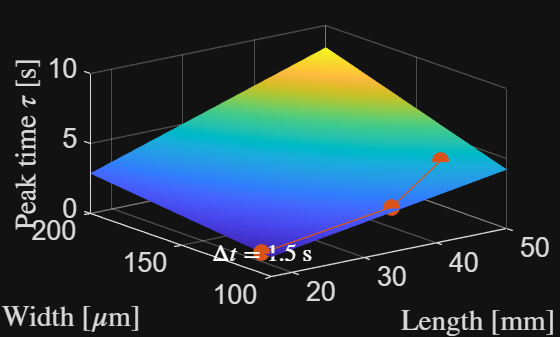

w_3=w_vec(row);


% Plotting the surface for the peak_tau matrix
figure;
s=surf(l_vec*1e3, w_vec*1e6, h_tau);hold on;
% Superposing the tau_coords on the plot
plot3([L_1 L_2 L_3]*1e3, [w_1 w_2 w_3]*1e6, tau_sample*[1 2 3], 'o-',...
    'MarkerSize', 12, 'Color','#D95319','MarkerFaceColor','#D95319');
%annotation for the sampling time
text(L_1*1e3,w_1*1e6,tau_sample,{strcat('$\Delta t=',num2str(tau_sample,2),'$ s')},'FontSize',fontsize-2,'Color','w','HorizontalAlignment','center',Interpreter='latex');

s.EdgeColor = 'none';
xlabel('Length [mm]','Interpreter','latex');
ylabel('Width [$\mu$m]','Interpreter','latex');
zlabel('Peak time $\tau$ [s]','Interpreter','latex');
% title('Pipe 1')
%axis([l_vec(1)*1e3 l_vec*1e3 w_vec(1)*1e6 w_vec*1e6])
set(gca, 'YDir', 'normal');
set(gca,'FontSize',fontsize ,'YDir', 'normal'); % To display the y-axis in the correct direction


%Pipe 1
%Flow to the pipe 1 in a single connection
%resistance of the rectangular Pipe 1
% R_1=12*mu_Water*L_1/(1-0.63*height_pipe/w_1)*(1/(height_pipe^3*w_1))
% Q_1=p0/R_1;
% Q_1_uL_min=Q_1*6e10

%mean velocity
%Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
v_char=Q/(w_1*height_pipe)

v_char = 0.0113


%Peclet number, see [3, Eq. below 11] 
Pe=v_char*height_pipe/D_coeff

Pe = 647.5667


%Evaluating the Effective Diffusion coefficient
%Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
%Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
D_eff=D_coeff*(1+1/200*Pe^2)

D_eff = 1.0279e-06

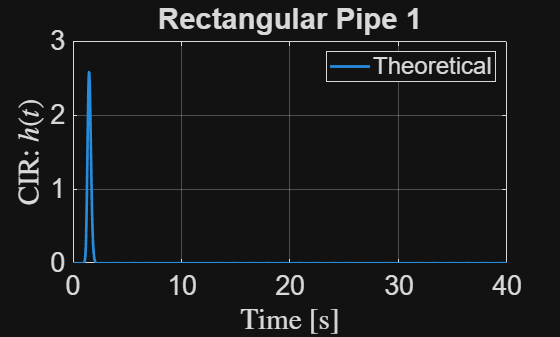


time=0:time_delta:time_simul;
%Evaluating the concentration of the straigth channel
conc_Pipe_1_Theo=1./2.*erfc((L_1-v_char*time)./(2*sqrt(D_eff*time)));
% %Evaluating the channel impulse response
h_cir_1_Theo=gradient(conc_Pipe_1_Theo,time);

figure;
plot(time,h_cir_1_Theo,'LineWidth',2); grid on; hold on;
xlabel("Time [s]",'Interpreter','latex');
ylabel("CIR: $h(t)$",'Interpreter','latex');
title("Rectangular Pipe 1")
set(gca,'FontSize',fontsize);
legend({'Theoretical','COMSOL'},'Location','northeast');

# CAD design of the CNN-like structure

**Description:** This code evaluates the coordinates for the upper lines and lower lines for each pipe. As represented on Fig. 1, we define each pipe coordinates with points.

Figure 1: Reference points on the design.

## Inlet dimensions

%this reference coordinates are coming from the original CAD desing. This
%two points reference refer to the pipe just after the mixer on the
%transmitter side. See Fig. 1.
% P_u0=[-42.36063776 1.75826183]*1e-3;
% P_b0=[-42.36063776 1.65926683]*1e-3;
%width for the mixer pipe, this is taken from [4]
% w_0=P_u0(2)-P_b0(2);
w_0=98.995*1e-6;%measured with the design COMSOL_3D_CNN_Design_1_2.mph, placed at \COMSOL_CNN_height_38um_Q_2_2_uL_tetrazine_Design_1\CAD_design
fprintf('w_0=%.8f um', w_0*1e6);   % fixed-point with 15 decimals

w_0=98.99500000 um

%length of the inlet
L_0=210e-6;
fprintf('L_0=%.8f mm', L_0*1e3);   % fixed-point with 15 decimals

L_0=0.21000000 mm

## Center shape

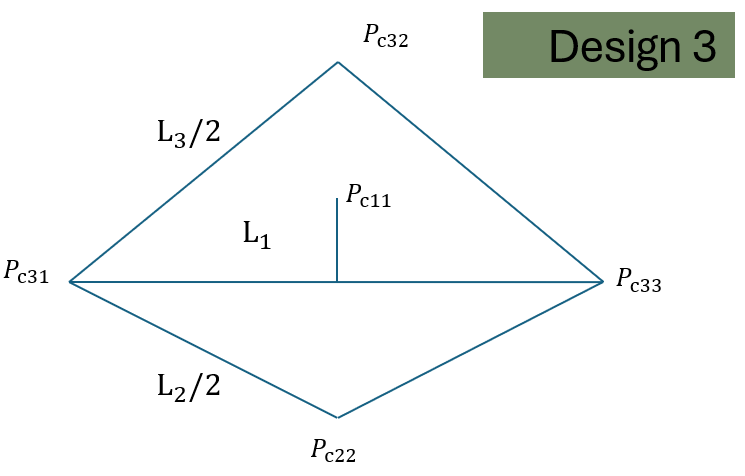

Figure 2: Reference points for the center triangles.

### Center coordinates for the two top and bottom triangles in Figure 2

% basic validity checks (optional)
if L_3 < L_1 || L_2 < L_1
    error('Need L2 >= L1 and L3 >= L1 to form valid isosceles triangles.');
end

% base endpoints
Pc31 = [0, 0];
Pc33 = [L_1, 0];

% heights of upper and lower triangles
h_3 = sqrt( (L_3/2)^2 - (L_1/2)^2 );
h_2 = sqrt( (L_2/2)^2 - (L_1/2)^2 );

% apex of upper triangle
Pc32 = [L_1/2,  h_3];

% apex of lower triangle
Pc22 = [L_1/2, -h_2];

% Pc11
Pc11= [L_1/2, L_1/2];

%Center polygon
% Stack all vertices row by row
coords = [Pc31; Pc32; Pc33; Pc22; Pc31; Pc33];
%saving in the CSV file
outputFile = fullfile(pwd, 'dataset', 'polygon_center.csv'); % build full path safely
writematrix(coords, outputFile);

### Upper polygon center

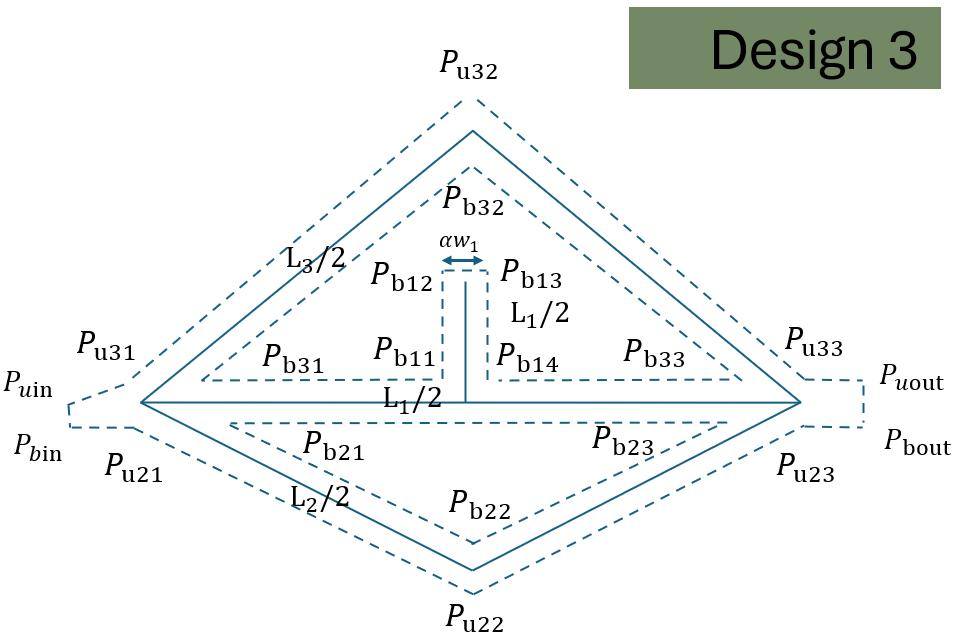

Figure 3: Reference points for the polygon outer.

% Inner triangle vertices

% Pb32: intersection of the two offset slanted sides
x_b32 = L_1/2;
y_b32 = h_3 - (w_3 * L_3) / (2 * L_1);
Pb32  = [x_b32,  y_b32];

% Pb31: left bottom vertex (offset left side & y = w_1/2)
x_b31 = (L_3 * w_3 + L_1 * w_1) / (4 * h_3);
y_b31 =  w_1 / 2;
Pb31  = [x_b31,  y_b31];

% Pb33: right bottom vertex (offset right side & y = w_1/2)
x_b33 = L_1 - x_b31;
y_b33 =  w_1 / 2;
Pb33  = [x_b33,  y_b33];

alpha=3;
% Pb11
Pb11 = Pb31+[L_1/2-alpha*w_1/2, 0];
% Pb12
Pb12 = Pb11+[0,L_1/2];
% Pb13
Pb13 = Pb12+[alpha*w_1,0];
% Pb14
Pb14 = Pb11+[alpha*w_1,0];

%Upper polygon
% Stack all vertices row by row
coords = [Pb31; Pb11; Pb12; Pb13; Pb14; Pb33; Pb32; Pb31];
%saving in the CSV file
outputFile = fullfile(pwd, 'dataset', 'polygon_upper.csv'); % build full path safely
writematrix(coords, outputFile);

% height of lower outer triangle
h_2 = sqrt( (L_2/2)^2 - (L_1/2)^2 );

% ---- inner lower triangle vertices ----

% Pb21: left top vertex (offset left side & y = -w_1/2)
x_b21 = (L_2 * w_2 + L_1 * w_1) / (4 * h_2);
y_b21 = -w_1 / 2;
Pb21  = [x_b21, y_b21];

% Pb22: apex of inner lower triangle
x_b22 = L_1 / 2;
y_b22 = -h_2 + (L_2 * w_2) / (2 * L_1);
Pb22  = [x_b22, y_b22];

% Pb23: right top vertex (offset right side & y = -w_1/2)
x_b23 = L_1 - x_b21;
y_b23 = -w_1 / 2;
Pb23  = [x_b23, y_b23];

%Bottom polygon 
% Stack all vertices row by row
coords = [Pb21; Pb22; Pb23; Pb21];
%saving in the CSV file
outputFile = fullfile(pwd, 'dataset', 'polygon_bottom.csv'); % build full path safely
writematrix(coords, outputFile);

%Outer polygon
% Pu32
Pu32 = [L_1/2, h_3 + (w_3 * L_3) / (2 * L_1)];
% Pu31
Pu31 = [0, (w_3 * L_3) / (2 * L_1)];
% Pu33
Pu33 = [L_1,  (w_3 * L_3) / (2 * L_1)];
% Pu22
Pu22 = [L_1/2, -h_2 - (w_2 * L_2) / (2 * L_1)];
% Pu21
Pu21 = [0, - (w_2 * L_2) / (2 * L_1)];
% Pu23
Pu23 = [L_1, - (w_2 * L_2) / (2 * L_1)];

%P_bin
Pbin=[-L_0/2,-w_0/2]

Pbin = 1.0e-03 *

   -0.1050   -0.0495


%P_uin
Puin=[-L_0/2,w_0/2]

Puin = 1.0e-03 *

   -0.1050    0.0495



%P_uout
Puout=Pu33+[L_0,0];
%P_bout
Pbout=[Puout(1),Pu23(2)]

Pbout =     0.0172   -0.0001



%Outer polygon 
% Stack all vertices row by row
coords = [Puin; Pu31; Pu32; Pu33; Puout; Pbout; Pu23; Pu22; Pu21; Pbin; Puin];
%saving in the CSV file
outputFile = fullfile(pwd, 'dataset', 'polygon_outer.csv'); % build full path safely
writematrix(coords, outputFile);

function addingPathParentFolderByName(targetName)
    % Start from the current directory
    currFolder = pwd;
    found = false;
    
    % Continue searching until you reach the root folder
    while true
        % Get the parent folder
        [parentFolder, currentName] = fileparts(currFolder);
        
        % Check if the current folder's name is the target
        if strcmpi(currentName, targetName)
            found = true;
            break;
        end
        
        % If we've reached the root or no change, exit the loop
        if isempty(parentFolder) || strcmp(currFolder, parentFolder)
            break;
        end
        
        % Move one level up
        currFolder = parentFolder;
    end

    if found
        addpath(genpath(currFolder));
        fprintf('Adding matlab path to: %s\n', currFolder);
    else
        error('Folder named "%s" not found in any parent directory.', targetName);
    end
end

function [value,factor]= getVarTable(var,table)
%This function extract the value of the variable specified in the entry var within
%the table specified in entry table

varName = inputname(1);

%find the corresponding entry within the table of parameters
for i=1:numel(table(:,1))
    entry_str=strcmp(table{i,1},varName);
    if entry_str
        entry_table=i;
        break
    end
end

%validating
if isempty(entry_table)
    error('Table has no column named "%s".', varName);
    value=NaN;
    factor=NaN;
else
    %reading the value in the second column of the table
    str=table{entry_table,2};
    if(isempty(findstr(str{1},'[')))
        value=table{entry_table,2};
    else
        value=extractBefore(table{entry_table,2},'[');
    end
    %reading the units of the value within the second column in the table
    unit = extractBetween(table{entry_table,2}, "[", "]"); % e.g. ["um"; "mm"; "nm"; "m"]
    if isempty(unit)
        factor=1;
    else
        %Define your conversion map to meters
        convMap = containers.Map( ...
            {'nm','um','mm','cm','m','km','rad','s','ms','us','ns','Pa','mmHg','m/s','mol/m^3','mol/L','m^2/s','cm^2/s','g/mol'}, ...
            [1e-9,1e-6,1e-3,1e-2,1,1e3,1,1,1e-3,1e-6,1e-9,1,133.322,1,1,1e3,1,1e-4,1e-3] );
        %Finding the conversion factors
        if isKey(convMap, unit)
            factor = convMap(unit{1});
        else
            error('Unit "%s" not recognized.', unit{1});
        end
    end

end
end

function varName = getVarName(var)
%This function extract the value of the variable specified in var within
%the table specified in table

% getVarName   Extract the name of the workspace variable
varName = inputname(1);
end

function trow = makeRow(var, description, unit, scale)
    name = inputname(1);
    valStr = sprintf('%g[%s]', var*scale, unit);
    trow = table(string(name), string(valStr), string(description), ...
                 'VariableNames', {'Name','Value','Description'});
end

function trow = makeRow_no_unit(var, description)
    name = inputname(1);
    valStr = sprintf('%g', var);
    trow = table(string(name), string(valStr), string(description), ...
                 'VariableNames', {'Name','Value','Description'});
end


## References

[1] H. Bruus, *Theoretical Microfluidics*. 2008. doi: [10.1093/oso/9780199235087.001.0001](https://doi.org/10.1093/oso/9780199235087.001.0001).  

[2] Howard C. Berg. 1993. Random Walks in Biology. Princeton University Press.

[3] M. L. Parks and L. A. Romero, “Taylor–Aris dispersion in high aspect ratio columns of nearly rectangular cross section,” *Mathematical and Computer Modelling*, vol. 46, no. 5, pp. 699–717, Sep. 2007, doi: [10.1016/j.mcm.2006.11.029](https://doi.org/10.1016/j.mcm.2006.11.029). 

[4] Murat paper